## Plot data and external control signal

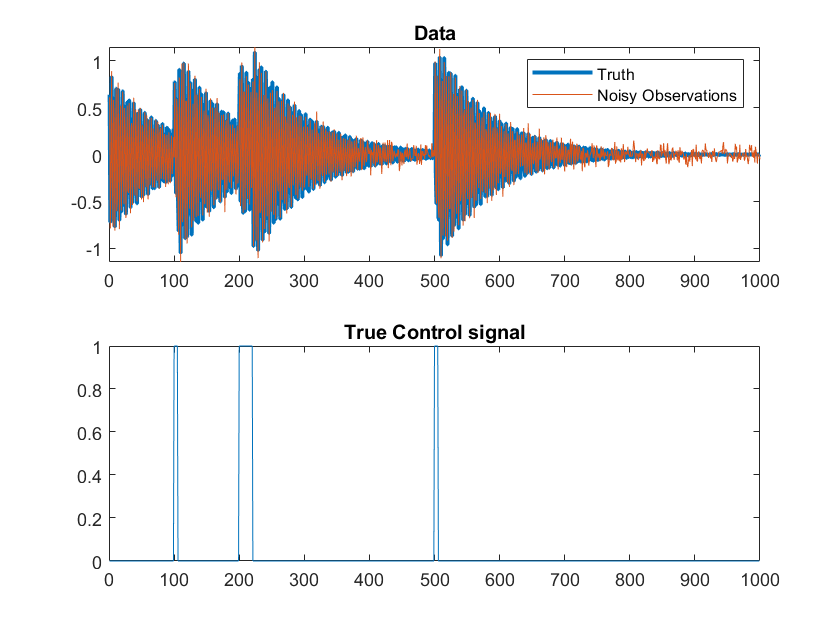

% Build example dynamics matrix
seed = 17;
n = 2;                  % Matrix size; should be even
m = 1000;               % Number of data points
eigenvalue_min = 0.95;  % Minimum eigenvalue; 1.0 = stable
[X_dmd, A] = test_dmd_dat(n, m, 0, eigenvalue_min, seed);

% Build several random controllers
ctr_timing = [100:105, 200:220, 500:505];
U = zeros(1,m-1);
U(ctr_timing) = 1.0;

% Generate controlled data
x0 = X_dmd(:,1);
B = ones(n,1);
X_true = real(calc_reconstruction_dmd(x0, [], A, B, U));
% Add noise
noise = 0.05;
X_raw = X_true + noise*randn(size(X_true));

% Plot
figure;

subplot(2,1,1)
plot(1:m,X_true(1,:), 'LineWidth',2)
hold on
plot(1:m,X_raw(1,:))
title("Data")
legend(["Truth", "Noisy Observations"])

subplot(2,1,2)
plot(1:m-1,U)
title("True Control signal")

## What to do if only 1 dimension is available?

Time delay embedding!

% We only see one dimension
X = X_raw(1,:);

% Augment with (excessive) delays
num_delays = 2;
X_embed = time_delay_embed(X, num_delays);

X = X_embed;

% Reduce dimensionality with SVD; try to learn optimal dimension
% num_dimensions = optimal_truncation(X_embed);
% [~, D, V] = svd(X_embed); 
% X = D(1:num_dimensions,1:num_dimensions)*V(:,1:num_dimensions)';

% % Plot new dimensions
% figure;
% plot(X')
% title(sprintf("%d Dimensions revealed using Time Delay Embedding", num_dimensions))
% legend()
% 
% figure;
% plot(X_true')
% title('The original dimensions')

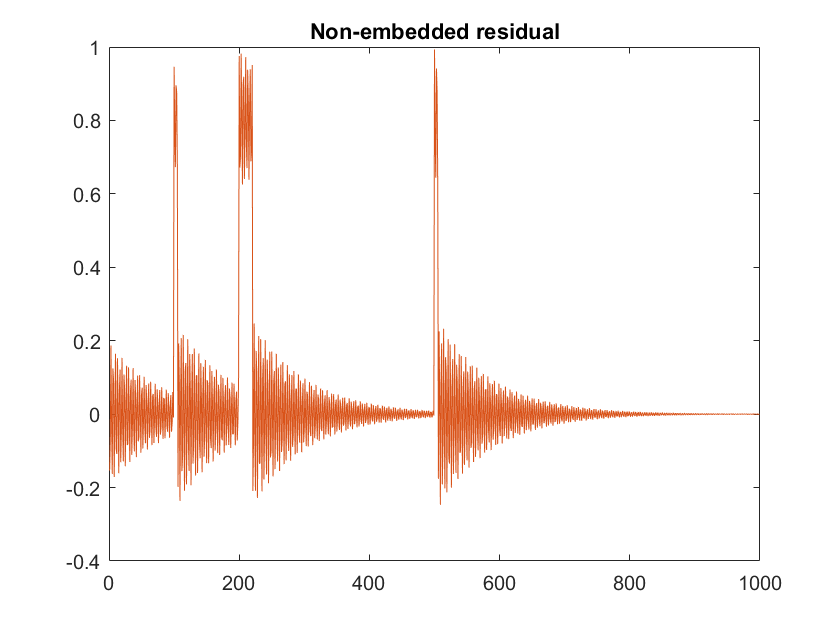

% Test: What if we don't embed?
X1 = X_true(:, 1:end-1);
X2 = X_true(:, 2:end);
A1 = X2/X1;

res1 = X2 - A1*X1;

figure;
plot(res1')
title('Non-embedded residual')

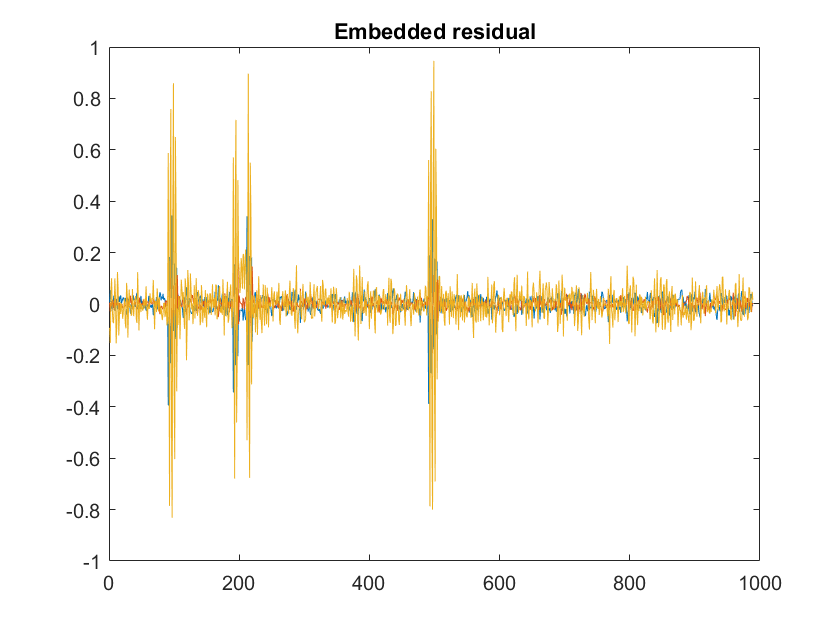



% Test: What is the embedded residual?
X1 = X(:, 1:end-1);
X2 = X(:, 2:end);
A2 = X2/X1;

res2 = X2 - A2*X1;

figure;
plot(res2')
title('Embedded residual')

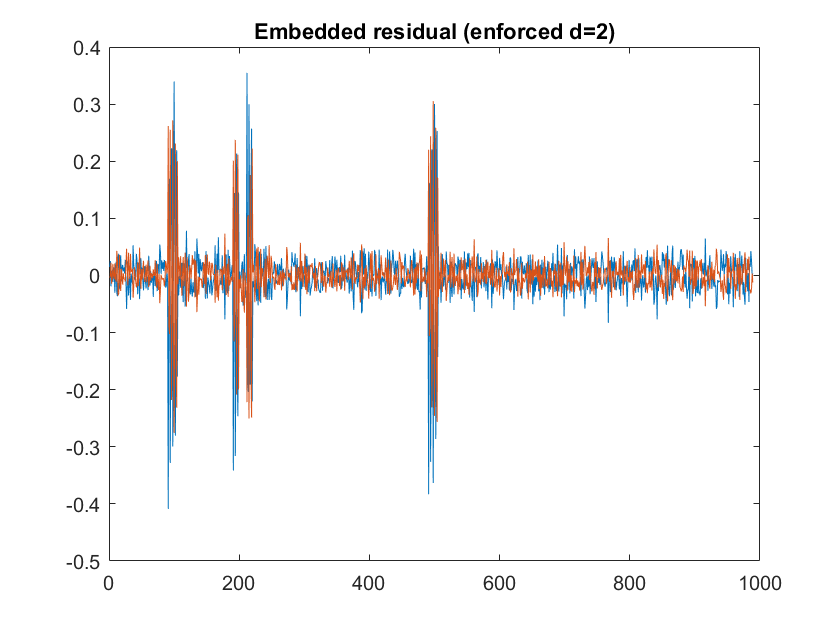


% Test: what if we enforce the true dimensionality?
X1 = X(1:2, 1:end-1);
X2 = X(1:2, 2:end);
A2 = X2/X1;

res = X2 - A2*X1;

figure;
plot(res')
title('Embedded residual (enforced d=2)')

% Can I get the unmeasured coordinate from the embed of the first?
% X_unmeasured = X_raw(2,1:990);
% B = X_unmeasured/X_embed;

Error using  / 
Matrix dimensions must agree.

% 
% res = X_unmeasured - B*X_embed;
% 
% figure;
% plot(res')

## Attempt 1: Learn the control signal

% Returns a data class with control signals of increasing sparsity
settings = struct('r_ctr',1, ... % Number of control signals to search for
                  'verbose',false, ... 
                   'num_iter',100); % Number of iterations
control_signal_path = learn_control_signals(X, settings);

All control signals are 0. Stopping early (this is nothing to worry about)



% Calculate best control signal
objective_function = 'aic_window';
lambda = {5};
control_signal_path.calc_best_control_signal(objective_function)

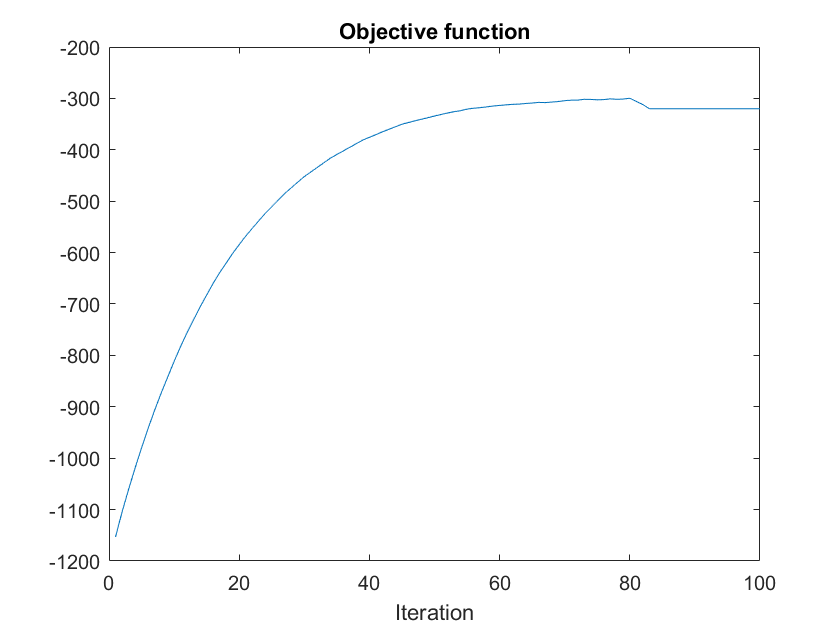


best_U = control_signal_path.U;

% Plot
objective_vals = control_signal_path.objective_values;

figure;
plot(objective_vals)
title('Objective function')
xlabel('Iteration')

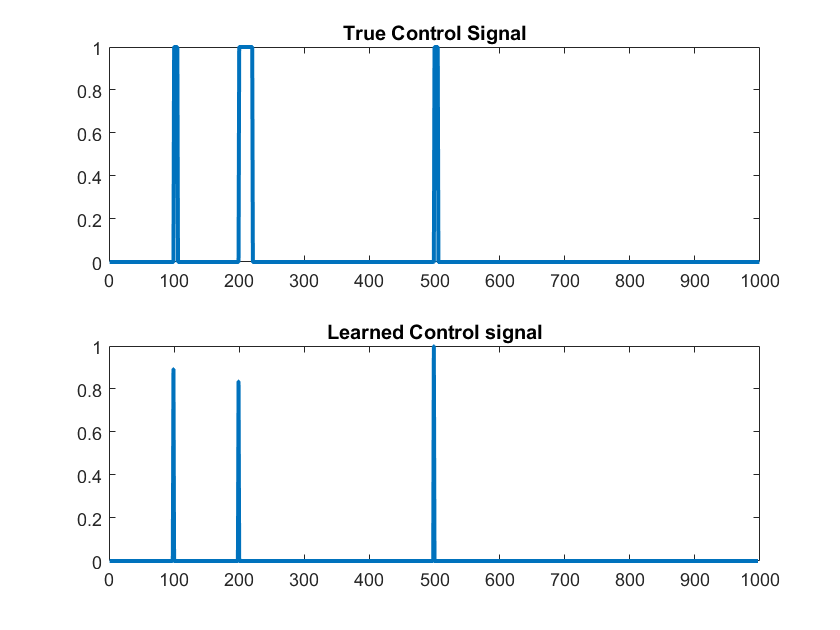


figure;
subplot(2,1,1)
plot(U, 'linewidth', 2)
title("True Control Signal")
subplot(2,1,2)
plot(best_U, 'linewidth', 2)
title("Learned Control signal")

## Attempt 2: Learn the control signal, but smooth the initialization

% Use the same base settings from before
settings.to_smooth_initialization = true;
settings.initialization_smoothing_windows = [3, 3];
control_signal_path2 = learn_control_signals(X, settings);

All control signals are 0. Stopping early (this is nothing to worry about)



% Calculate best control signal (same objective function as before)
control_signal_path2.calc_best_control_signal(objective_function, lambda);

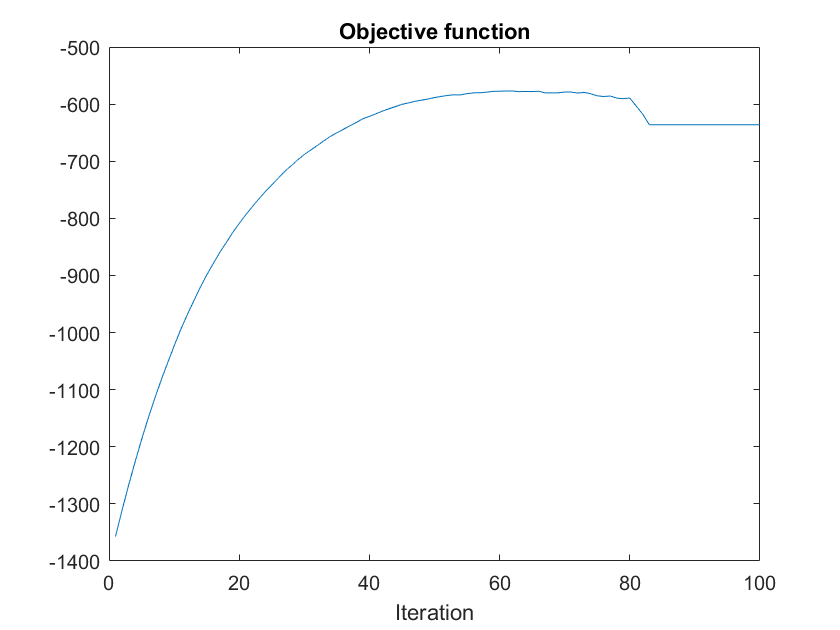


best_U2 = control_signal_path2.U;

% Plot
objective_vals = control_signal_path2.objective_values;

figure;
plot(objective_vals)
title('Objective function')
xlabel('Iteration')

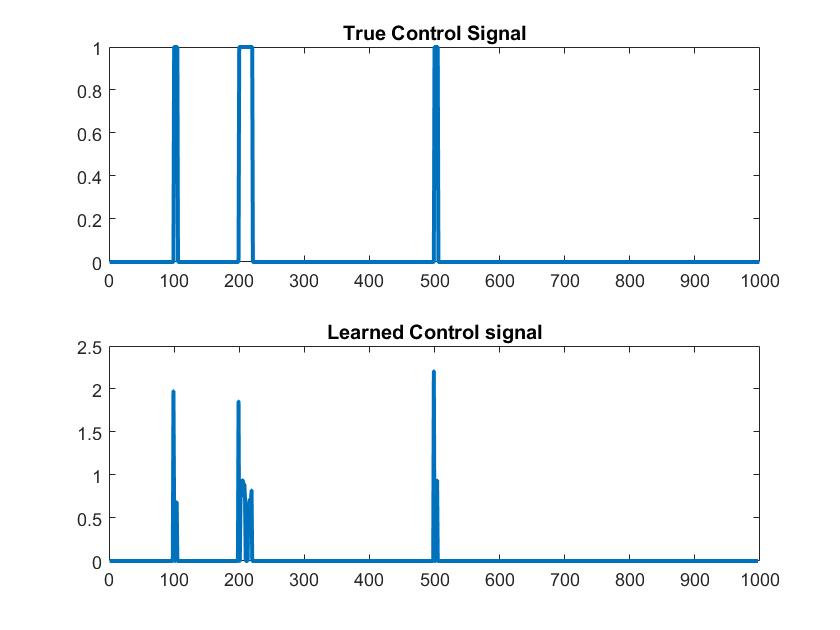


figure;
subplot(2,1,1)
plot(U, 'linewidth', 2)
title("True Control Signal")
subplot(2,1,2)
plot(best_U2, 'linewidth', 2)
title("Learned Control signal")

## Do DMDc using learned control signal

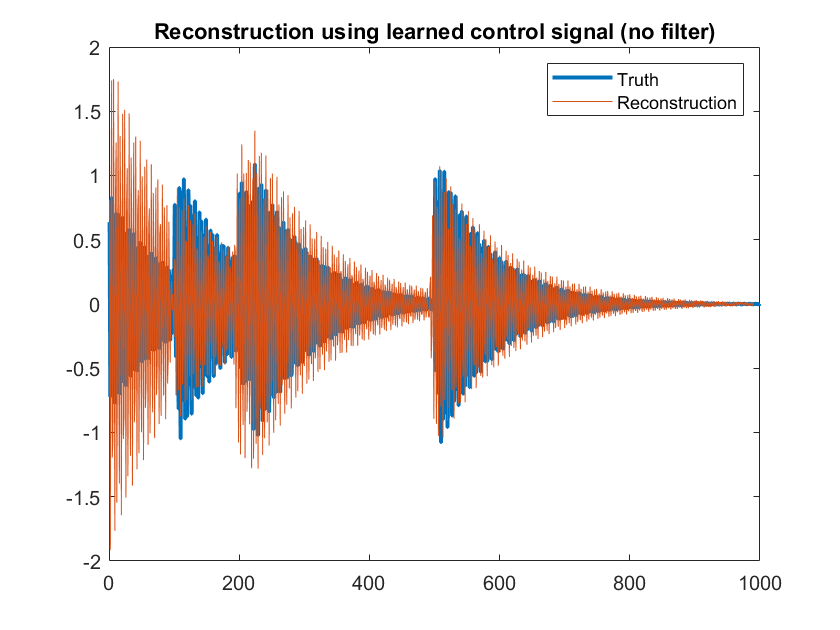

% Get learned matrices: no filtering
[best_A, best_B, learned_X] = simple_dmdc(X, best_U);
% Get learned matrices: with filtering
[best_A2, best_B2, learned_X2] = simple_dmdc(X, best_U2);

% Plot
figure;
plot(X_true(1,:), 'linewidth', 2)
hold on
plot(learned_X(1,:))
legend("Truth", "Reconstruction")
title("Reconstruction using learned control signal (no filter)")

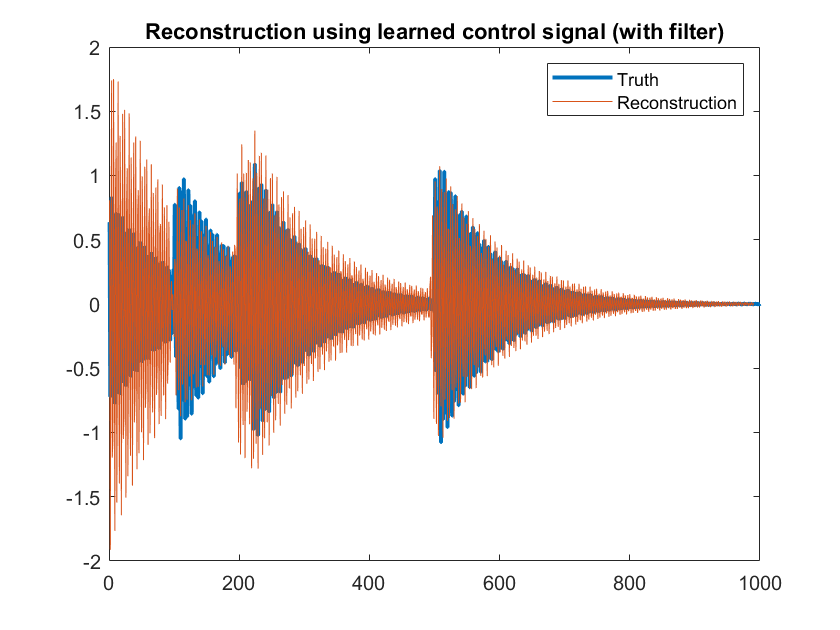


figure;
plot(X_true(1,:), 'linewidth', 2)
hold on
plot(learned_X2(1,:))
legend("Truth", "Reconstruction")
title("Reconstruction using learned control signal (with filter)")